clear

load('data\Phi.mat')

c_real = zeros(size(Phi,3),6);
c_imag = zeros(size(Phi,3),6);
for k = 1:size(Phi,3)
    [z, c_real(k,:)] = depthProfile(vecnorm(real(Phi(:,:,k))), voxels_center);
    [z, c_imag(k,:)] = depthProfile(vecnorm(imag(Phi(:,:,k))), voxels_center);
end

i = optimvar("i", 4, "Type","integer", "LowerBound",1, "UpperBound",size(Phi,3));

% prob = optimproblem("ObjectiveSense","maximize");
% prob.Objective = fcn2optimexpr(@(i)svds([c_real(i,:); c_imag(i,:)], 1, 'smallest'), i);

prob = optimproblem("ObjectiveSense","minimize");
prob.Objective = fcn2optimexpr(@(i)cond([c_real(i,:); c_imag(i,:)]), i);

constr = optimconstr(length(i));
for a = 1:length(i)
    if a == 1
        constr(a) = i(a) >= 10;
    else
        constr(a) = i(a) >= i(a-1) + 5;
    end
end
prob.Constraints = constr;

show(prob);


  OptimizationProblem : 

	Solve for:
       i
	where:
       i integer

	minimize :
       anonymousFunction1(i)

       where:

           anonymousFunction1 = @(i)cond([c_real(i,:);c_imag(i,:)]);


	subject to :
       i(1) >= 10
       -i(1) + i(2) >= 5
       -i(2) + i(3) >= 5
       -i(3) + i(4) >= 5

	variable bounds:
       1 <= i(1) <= 100
       1 <= i(2) <= 100
       1 <= i(3) <= 100
       1 <= i(4) <= 100




[sol, obj_value] = solve(prob, "Solver","ga");

Solving problem using ga.
Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.



i = sol.i

i =     10
    25
    30
   100


obj_value

obj_value = 8.5577e+03

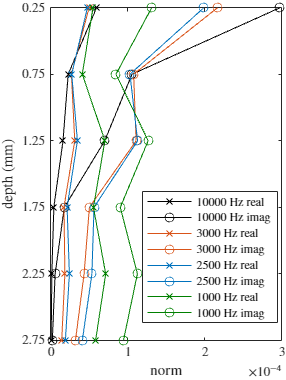

colors = {};
colors{end+1} = [0.0000 0.0000 0.0000];
colors{end+1} = [0.8500 0.3250 0.0980];
colors{end+1} = [0.0000 0.4470 0.7410];
colors{end+1} = [0.0000 0.5000 0.0000];
colors{end+1} = [0.4940 0.1840 0.5560];
colors{end+1} = [0.6350 0.0780 0.1840];
colors{end+1} = [0.2500 0.2500 0.2500];

figure('Position',[300 300 260 345])
tiledlayout(1,1, 'TileSpacing','none', 'Padding','none')
nexttile
hold on

k = 0;
for i = [100 30 25 10]
    k = k + 1;

    c = c_real(i,:);
    label = sprintf("%g Hz real", freqs(i));
    plot(c, -z*1e3, '-x', 'Color',colors{k}, 'DisplayName',label)

    c = c_imag(i,:);
    label = sprintf("%g Hz imag", freqs(i));
    plot(c, -z*1e3, '-o', 'Color',colors{k}, 'DisplayName',label)
end

set(gca, 'YDir','reverse')
ylim([0.25 2.75])
yticks(0.25:0.5:3)
xlabel('norm')
ylabel('depth (mm)')
legend('Location','best')
box on

function [z, c_sum] = depthProfile(c, pos)

assert(isreal(c))
assert(size(c,2) == size(pos,2))

z = unique(pos(3,:));
z = sort(z, 'descend');

c_sum = zeros(size(z));
for k = 1:length(z)
    mask = pos(3,:) == z(k);
    c_sum(k) = sum(c(mask));
end

end